# Non-Isentropic Ramjet Calculator

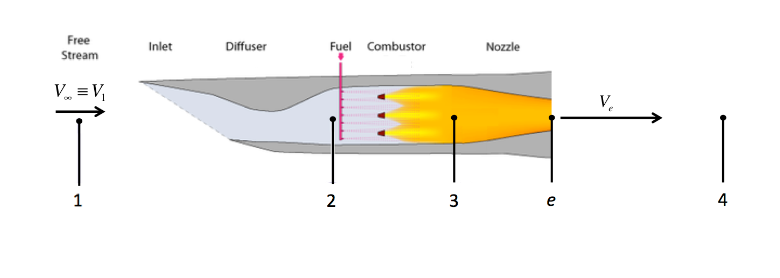

## Module 7- Thermally Unchoked Check

clear
alt =4300; %flight alt-- m
eta_d = .92; %inlet eff.
eta_n = .94; %nozzle eff.
A_e = .015; %m^2
M1 = 2.4;
M2= .15;
Tt3_max = 2400; %k
qf = 42.3*10^6; %j/kg
[T, Tt, P, Pt, V, M, cp, deltaS, Thermal_efficiency, Propulsive_efficiency, Overall_efficiency, Power,Thrust, Isp, TSFC, MassFlux, f, q23] = RamjetCalculator(alt, eta_d, eta_n, A_e, M1, M2, Tt3_max, qf);
states = ['1', '2', '3', 'e', '4'];

%results
InputsTable = table(alt, eta_d, eta_n, A_e,M1, M2, Tt3_max,qf, 'VariableNames',{'Flight Altitude','Diffuser Eff.', 'Nozzle Eff.', 'A_e','M1', 'M2','Tt3_max', 'q_f' }  )

InputsTable = 1×8 table
    Flight Altitude    Diffuser Eff.    Nozzle Eff.     A_e     M1      M2     Tt3_max      q_f   
    _______________    _____________    ___________    _____    ___    ____    _______    ________

         4300              0.92            0.94        0.015    2.4    0.15     2400      4.23e+07


StatesTable =table(states',T', Tt', P', Pt', V', M', cp', 'VariableNames',{'States','T','Tt','P','Pt','V','M', 'Cp'})

StatesTable = 5×8 table
    States      T         Tt        P         Pt        V          M         Cp  
    ______    ______    ______    ______    ______    ______    _______    ______

      1        245.9    529.17    58.261    851.77    754.25        2.4    1004.2
      2        526.8    529.17     719.4    730.79    68.999       0.15    1004.2
      3       2354.3      2400     719.4    781.89    337.07    0.35971    1407.4
      e         2087      2400    409.28    749.96    882.25          1    1359.6
      4       1557.7      2400    58.261    379.21    1447.2     1.8987    1264.8


PerformanceStatistics = table(Thermal_efficiency, Propulsive_efficiency, Overall_efficiency, Power,Thrust, Isp, TSFC, f, q23, 'VariableNames',{'Thermal efficiency', 'Propulsive efficiency', 'Overall efficiency', 'Power', 'Thrust', 'Isp', 'TSFC', 'f', 'q23'})

PerformanceStatistics = 1×9 table
    Thermal efficiency    Propulsive efficiency    Overall efficiency      Power       Thrust     Isp       TSFC         f           q23    
    __________________    _____________________    __________________    __________    ______    ______    _______    ________    __________

         0.36265                 0.67995                0.24658          5.1139e+06    6780.1    1461.9    0.25128    0.055203    2.3351e+06


EntropyResults =table(deltaS(1),deltaS(2),deltaS(3),deltaS(4),deltaS(5),deltaS(6),deltaS(7), 'VariableNames',{'deltaS_12', 'deltaS_23', 'deltaS_3e', 'deltaS_e4', 'deltaS_13', 'deltaS_1e', 'deltaS_14'})

EntropyResults = 1×7 table
    deltaS_12    deltaS_23    deltaS_3e    deltaS_e4    deltaS_13    deltaS_1e    deltaS_14
    _________    _________    _________    _________    _________    _________    _________

     43.951       2108.5       11.961       195.65       2152.5       2164.4       2360.1  


MassFluxTable =table(MassFlux(1),MassFlux(2),MassFlux(3), 'VariableNames',{'Inlet Mass Flux','Outlet Mass Flux','Fuel Mass Flux'}) 

MassFluxTable = 1×3 table
    Inlet Mass Flux    Outlet Mass Flux    Fuel Mass Flux
    _______________    ________________    ______________

        8.5728              9.046             0.47324    


### Plotting T-S Diagram for Thermally Unchoked Check (a)

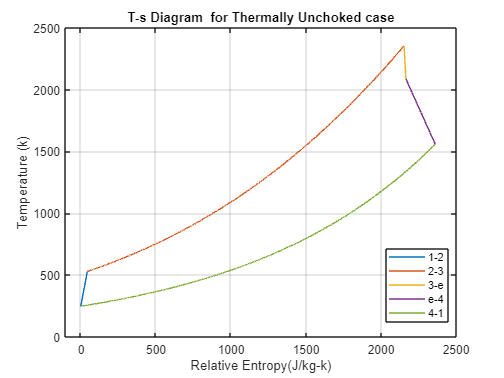

ds_23 = (deltaS(5)-deltaS(1))/10000;
s_23= deltaS(1):ds_23:deltaS(5);
T_23 = [];
T_23(1) = T(2);

for i = 1:length(s_23)-1
  T_23(i+1) = T_23(i) + (T_23(i)/(986 + .179*T_23(i)))*ds_23;
  if (T_23(i) >=T(3))
      break
  end
end
s_23 = linspace(deltaS(1), deltaS(5), length(T_23));

ds_41 = (deltaS(7))/10000;
s_41= 0:ds_41:deltaS(7);
T_41 = [];
T_41(1) = T(1);

for i = 1:length(s_41)-1
  T_41(i+1) = T_41(i) + (T_41(i)/1004)*ds_41;
    if (T_41(i) >=T(5))
      break
  end
end

s_41 = linspace(0, deltaS(7), length(T_41));

plot([0, deltaS(1)], [T(1), T(2)]) %1-2
hold on
plot(s_23,T_23) %2-3
plot([deltaS(5), deltaS(6)], [T(3), T(4)]) %3-e
plot([deltaS(6), deltaS(7)], [T(4), T(5)]) %e-4
plot(s_41,T_41) %4-1
legend({'1-2','2-3','3-e','e-4','4-1',}, 'Location','best')
xlabel('Relative Entropy(J/kg-k)')
ylabel('Temperature (k)')
title('T-s Diagram  for Thermally Unchoked case')
grid on
axis([-100 2500 0 2500])
hold off

## Module 8- Thermally Choked Check

alt =4300; %flight alt-- m
eta_d = .92; %inlet eff.
eta_n = .94; %nozzle eff.
A_e = .015; %m^2
M1 = 2.4;
M2= .4;
Tt3_max = 2400; %k
qf = 42.3*10^6; %j/kg
[T, Tt, P, Pt, V, M, cp, deltaS, Thermal_efficiency, Propulsive_efficiency, Overall_efficiency, Power,Thrust, Isp, TSFC, MassFlux, f, q23] = RamjetCalculator(alt, eta_d, eta_n, A_e, M1, M2, Tt3_max, qf);
states = ['1', '2', '3', 'e', '4'];

%results
InputsTable = table(alt, eta_d, eta_n, A_e,M1, M2, Tt3_max,qf, 'VariableNames',{'Flight Altitude','Diffuser Eff.', 'Nozzle Eff.', 'A_e','M1', 'M2','Tt3_max', 'q_f' }  )

InputsTable = 1×8 table
    Flight Altitude    Diffuser Eff.    Nozzle Eff.     A_e     M1     M2     Tt3_max      q_f   
    _______________    _____________    ___________    _____    ___    ___    _______    ________

         4300              0.92            0.94        0.015    2.4    0.4     2400      4.23e+07


StatesTable =table(states',T', Tt', P', Pt', V', M', cp', 'VariableNames',{'States','T','Tt','P','Pt','V','M', 'Cp'})

StatesTable = 5×8 table
    States      T         Tt        P         Pt        V         M         Cp  
    ______    ______    ______    ______    ______    ______    ______    ______

      1        245.9    529.17    58.261    851.77    754.25       2.4    1004.2
      2       512.76    529.17    654.51    730.79    181.53       0.4    1004.2
      3       890.95    1024.6    654.51    1199.3    576.45         1    1145.5
      e       890.95    1024.6    627.78    1150.4    576.45         1    1145.5
      4       634.58    1024.6    58.261    464.51    984.76    2.0242    1099.6


PerformanceStatistics = table(Thermal_efficiency, Propulsive_efficiency, Overall_efficiency, Power,Thrust, Isp, TSFC, f,q23, 'VariableNames',{'Thermal efficiency', 'Propulsive efficiency', 'Overall efficiency', 'Power', 'Thrust', 'Isp', 'TSFC', 'f', 'q23'})

PerformanceStatistics = 1×9 table
    Thermal efficiency    Propulsive efficiency    Overall efficiency      Power       Thrust     Isp       TSFC         f           q23    
    __________________    _____________________    __________________    __________    ______    ______    _______    ________    __________

         0.36028                 0.87047                0.31362          3.7526e+06    4975.3    1838.2    0.19984    0.013177    5.5738e+05


EntropyResults =table(deltaS(1),deltaS(2),deltaS(3),deltaS(4),deltaS(5),deltaS(6),deltaS(7), 'VariableNames',{'deltaS_12', 'deltaS_23', 'deltaS_3e', 'deltaS_e4', 'deltaS_13', 'deltaS_1e', 'deltaS_14'})

EntropyResults = 1×7 table
    deltaS_12    deltaS_23    deltaS_3e    deltaS_e4    deltaS_13    deltaS_1e    deltaS_14
    _________    _________    _________    _________    _________    _________    _________

     43.951       614.74       11.961       260.17       658.69       670.65       930.82  


MassFluxTable =table(MassFlux(1),MassFlux(2),MassFlux(3), 'VariableNames',{'Inlet Mass Flux','Outlet Mass Flux','Fuel Mass Flux'}) 

MassFluxTable = 1×3 table
    Inlet Mass Flux    Outlet Mass Flux    Fuel Mass Flux
    _______________    ________________    ______________

         20.96              21.236            0.27619    


### Plotting T-S Diagram for Thermally Choked Check (a)

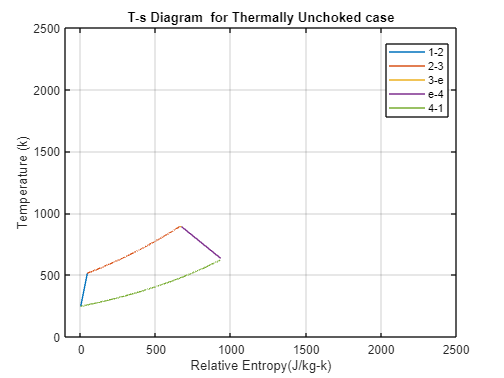

ds_23 = (deltaS(5)-deltaS(1))/10000;
s_23= deltaS(1):ds_23:deltaS(5);
T_23 = [];
T_23(1) = T(2);

for i = 1:length(s_23)-1
  T_23(i+1) = T_23(i) + (T_23(i)/(986 + .179*T_23(i)))*ds_23;
  if (T_23(i) >=T(3))
      break
  end
end
s_23 = linspace(deltaS(1), deltaS(5), length(T_23));

ds_41 = (deltaS(7))/10000;
s_41= 0:ds_41:deltaS(7);
T_41 = [];
T_41(1) = T(1);

for i = 1:length(s_41)-1
  T_41(i+1) = T_41(i) + (T_41(i)/1004)*ds_41;
    if (T_41(i) >=T(5))
      break
  end
end

s_41 = linspace(0, deltaS(7), length(T_41));

plot([0, deltaS(1)], [T(1), T(2)]) %1-2
hold on
plot(s_23,T_23) %2-3
plot([deltaS(5), deltaS(6)], [T(3), T(4)]) %3-e
plot([deltaS(6), deltaS(7)], [T(4), T(5)]) %e-4
plot(s_41,T_41) %4-1
legend({'1-2','2-3','3-e','e-4','4-1',}, 'Location','best')
xlabel('Relative Entropy(J/kg-k)')
ylabel('Temperature (k)')
title('T-s Diagram  for Thermally Unchoked case')
grid on
axis([-100 2500 0 2500])
hold off

## (b) Validation of Atmospheric Model 

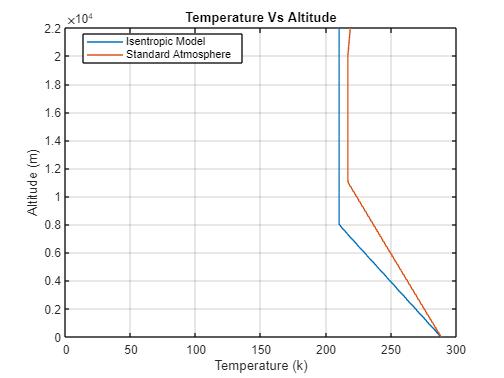

clear
StdAtmModelData = importdata('Validation of Atmospheric Model.xlsx');
z = StdAtmModelData.data(13:54, 5);
T_stdAtm = StdAtmModelData.data(13:54, 6);
P_stdAtm = StdAtmModelData.data(13:54, 7);

T_isen= [];
P_isen = [];

for i = 1:length(z)
[T_isen(i), P_isen(i),~,~] = IsenAltModel(z(i));
end

%T plot
plot(T_isen, z)
hold on
plot(T_stdAtm,z)
title('Temperature Vs Altitude')
xlabel('Temperature (k)')
ylabel('Altitude (m)')
grid on
axis([0 300 0 z(end)])
legend({'Isentropic Model', 'Standard Atmosphere'}, 'Location','best')
hold off

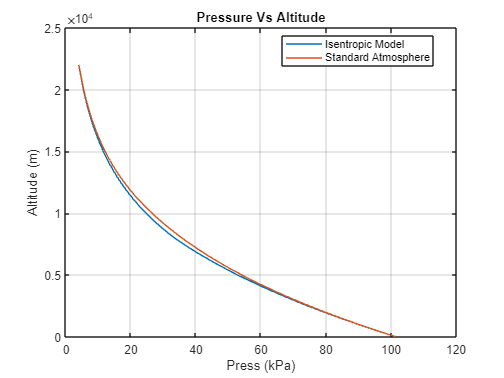


%P plot
plot(P_isen/1000, z)
hold on
plot(P_stdAtm,z)
title('Pressure Vs Altitude')
xlabel('Press (kPa)')
ylabel('Altitude (m)')
grid on
legend({'Isentropic Model', 'Standard Atmosphere'}, 'Location','best')
hold off

## (c) Flight mach number effects in unchoked case

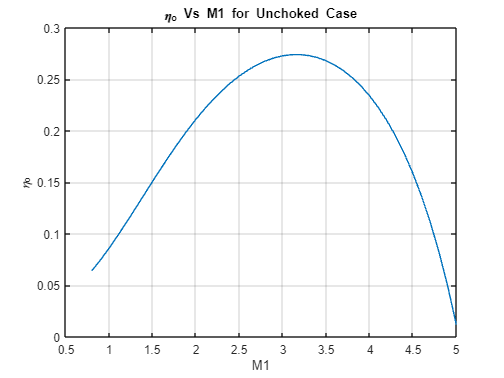

clear
alt =4300; %flight alt-- m
eta_d = .92; %inlet eff.
eta_n = .94; %nozzle eff.
A_e = .015; %m^2
M2= .15;
Tt3_max = 2400; %k
qf = 42.3*10^6; %j/kg

M1 = 0.8:.1:5;

Overall_efficiency_array = [];
Thrust_array = [];
TSFC_array = [];

for i = 1:length(M1)
    [~, ~,~,~, ~, ~, ~, ~, ~, ~, Overall_efficiency_array(i), ~,Thrust_array(i), ~, TSFC_array(i), V, ~, ~] = RamjetCalculator(alt, eta_d, eta_n, A_e, M1(i), M2, Tt3_max, qf);
    
end




plot(M1,Overall_efficiency_array)
title('\eta_o Vs M1 for Unchoked Case')
xlabel('M1')
ylabel('\eta_o')
grid on

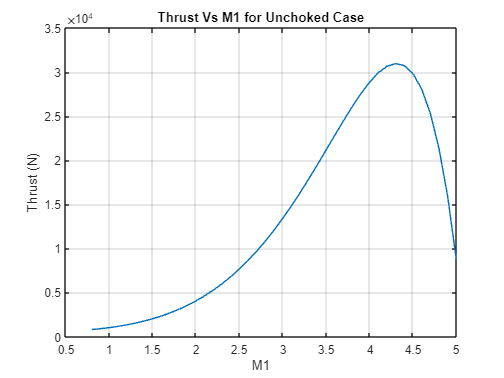


plot(M1,Thrust_array)
title('Thrust Vs M1 for Unchoked Case')
xlabel('M1')
ylabel('Thrust (N)')
grid on

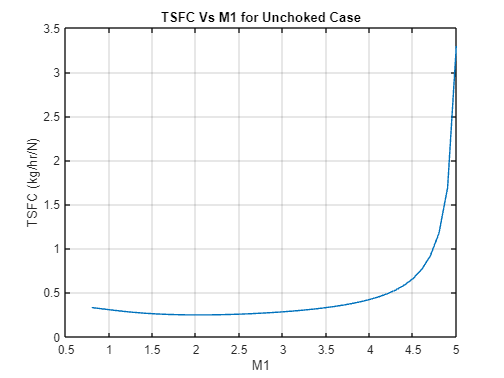


plot(M1,TSFC_array)
title('TSFC Vs M1 for Unchoked Case')
xlabel('M1')
ylabel('TSFC (kg/hr/N)')
grid on

## (d) Altitude effects in unchoked case

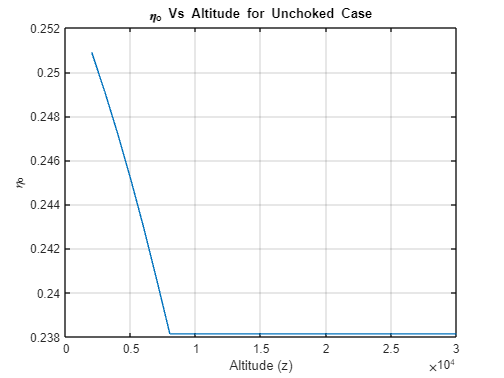

clear

eta_d = .92; %inlet eff.
eta_n = .94; %nozzle eff.
A_e = .015; %m^2
M1 = 2.4;
M2= .15;
Tt3_max = 2400; %k
qf = 42.3*10^6; %j/kg

alt = 2000:1000:30000;

Overall_efficiency_array = [];
Thrust_array = [];
TSFC_array = [];

for i = 1:length(alt)
    [~, ~,~,~, ~, ~, ~, ~, ~, ~, Overall_efficiency_array(i), ~,Thrust_array(i), ~, TSFC_array(i), ~, ~, ~] = RamjetCalculator(alt(i), eta_d, eta_n, A_e, M1, M2, Tt3_max, qf);
    
end


plot(alt,Overall_efficiency_array)
title('\eta_o Vs Altitude for Unchoked Case')
xlabel('Altitude (z)')
ylabel('\eta_o')
grid on

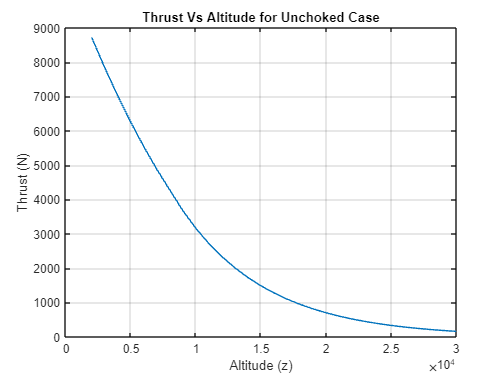


plot(alt,Thrust_array)
title('Thrust Vs Altitude for Unchoked Case')
xlabel('Altitude (z)')
ylabel('Thrust (N)')
grid on

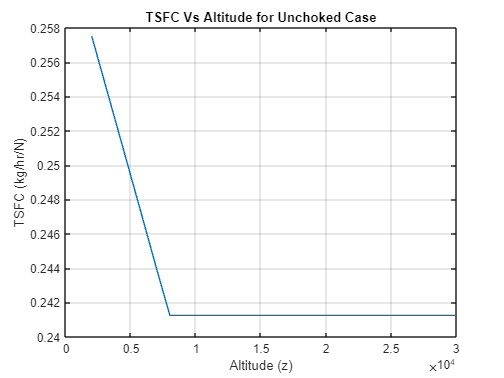


plot(alt,TSFC_array)
title('TSFC Vs Altitude for Unchoked Case')
xlabel('Altitude (z)')
ylabel('TSFC (kg/hr/N)')
grid on

## (e) Optimizing efficiency and TSFC

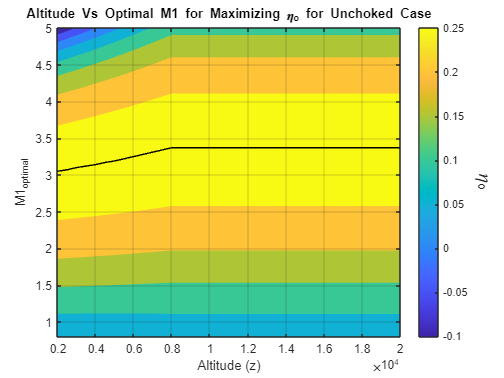

clear

eta_d = .92; %inlet eff.
eta_n = .94; %nozzle eff.
A_e = .015; %m^2
M2= .15;
Tt3_max = 2400; %k
qf = 42.3*10^6; %j/kg

alt = 2000:500:20000;
M1 = 0.8:.01:5;

Overall_efficiency_array = [];
TSFC_array = [];
OptimalM1_eta_o = [];
OptimalM1_TSFC = [];

[X, Y] = meshgrid(alt, M1);

for i = 1:length(alt)
    for j = 1:length(M1)
    [~, ~,~,~, ~, ~, ~, ~, ~, ~, Overall_efficiency_array(j), ~,~, ~, TSFC_array(j), ~, ~, ~] = RamjetCalculator(alt(i), eta_d, eta_n, A_e, M1(j), M2, Tt3_max, qf);
    eff_mesh(i,j) = Overall_efficiency_array(j);
    TSFC_grid(i,j) = TSFC_array(j);
    end
    [~, indx] = max(Overall_efficiency_array);
    OptimalM1_eta_o(i) = M1(indx);

    [~, indx] = min(TSFC_array);
    OptimalM1_TSFC(i) = M1(indx);
end

contourf(X,Y,eff_mesh', 'EdgeColor','none')
hold on
plot(alt,OptimalM1_eta_o,'k')
title('Altitude Vs Optimal M1 for Maximizing \eta_o for Unchoked Case')
xlabel('Altitude (z)')
ylabel('M1_{optimal}')
grid on
h = colorbar;
h.Label.FontSize = 16;
h.Label.String = '\eta_o';
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";
hold off

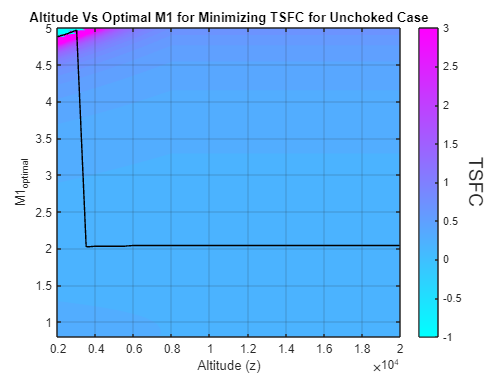



contourf(X,Y,TSFC_grid',3000, 'EdgeColor','none')
hold on
plot(alt,OptimalM1_TSFC, 'k')
title('Altitude Vs Optimal M1 for Minimizing TSFC for Unchoked Case')
xlabel('Altitude (z)')
ylabel('M1_{optimal}')
clim([-1,3])
h = colorbar;
h.Label.FontSize = 16;
h.Label.String = 'TSFC';
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";
colormap("cool")

grid on
hold off

## (f) Inlet/diffuser eff. effects in unchoked case

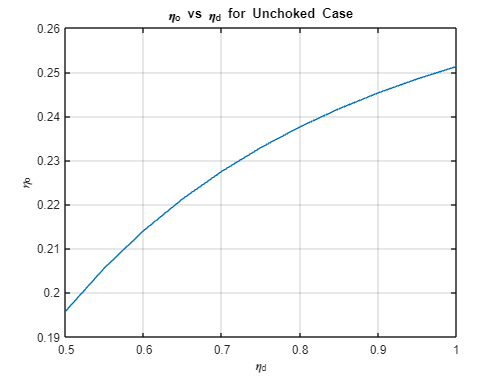

clear
alt =4300; %flight alt-- m
eta_n = .94; %nozzle eff.
A_e = .015; %m^2
M1 = 2.4;
M2= .15;
Tt3_max = 2400; %k
qf = 42.3*10^6; %j/kg

eta_d = .5:.05:1;

Overall_efficiency_array = [];
Thrust_array = [];
TSFC_array = [];

for i = 1:length(eta_d)
    [~, ~,~,~, ~, ~, ~, ~, ~, ~, Overall_efficiency_array(i), ~,Thrust_array(i), ~, TSFC_array(i), ~, ~, ~] = RamjetCalculator(alt, eta_d(i), eta_n, A_e, M1, M2, Tt3_max, qf);
end

plot(eta_d,Overall_efficiency_array)
title('\eta_o vs \eta_d for Unchoked Case')
xlabel('\eta_d')
ylabel('\eta_o')
grid on

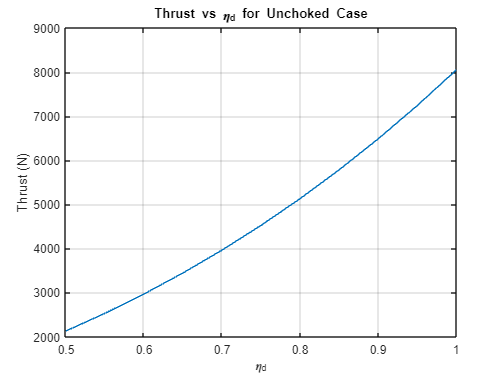


plot(eta_d,Thrust_array)
title('Thrust vs \eta_d for Unchoked Case')
xlabel('\eta_d')
ylabel('Thrust (N)')
grid on

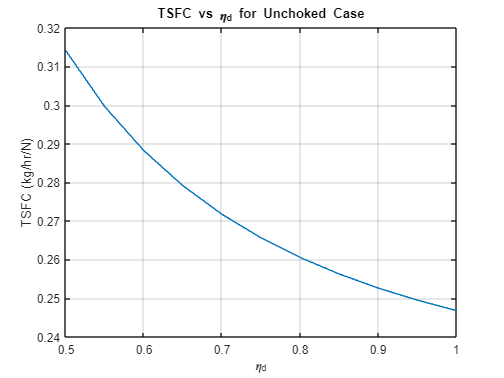


plot(eta_d,TSFC_array)
title('TSFC vs \eta_d for Unchoked Case')
xlabel('\eta_d')
ylabel('TSFC (kg/hr/N)')
grid on

## (g) Nozzle eff. effects in unchoked case

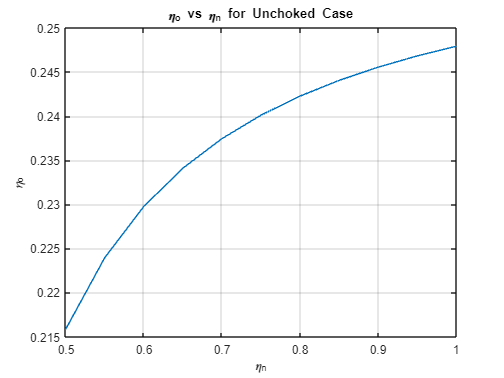

clear
alt =4300; %flight alt-- m
eta_d = .92;
A_e = .015; %m^2
M1 = 2.4;
M2= .15;
Tt3_max = 2400; %k
qf = 42.3*10^6; %j/kg

eta_n = .5:.05:1;

Overall_efficiency_array = [];
Thrust_array = [];
TSFC_array = [];

for i = 1:length(eta_n)
    [~, ~,~,~, ~, ~, ~, ~, ~, ~, Overall_efficiency_array(i), ~,Thrust_array(i), ~, TSFC_array(i), ~, ~, ~] = RamjetCalculator(alt, eta_d, eta_n(i), A_e, M1, M2, Tt3_max, qf);
end

plot(eta_n,Overall_efficiency_array)
title('\eta_o vs \eta_n for Unchoked Case')
xlabel('\eta_n')
ylabel('\eta_o')
grid on

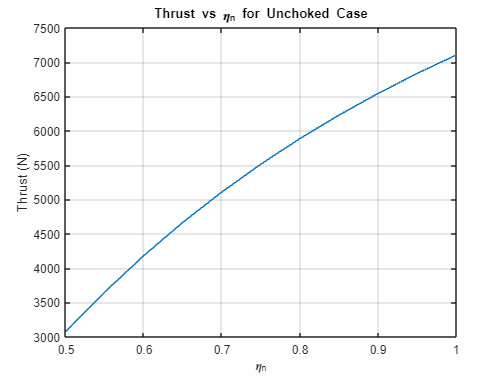


plot(eta_n,Thrust_array)
title('Thrust vs \eta_n for Unchoked Case')
xlabel('\eta_n')
ylabel('Thrust (N)')
grid on

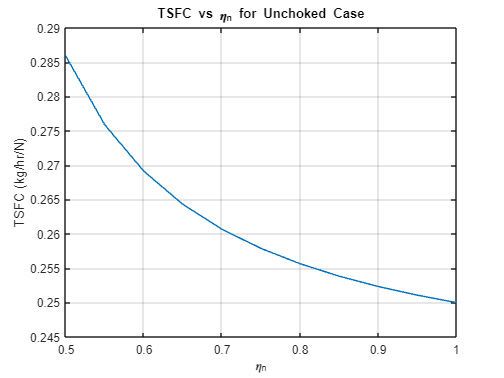


plot(eta_n,TSFC_array)
title('TSFC vs \eta_n for Unchoked Case')
xlabel('\eta_n')
ylabel('TSFC (kg/hr/N)')
grid on

## (h) M2 effects in unchoked case

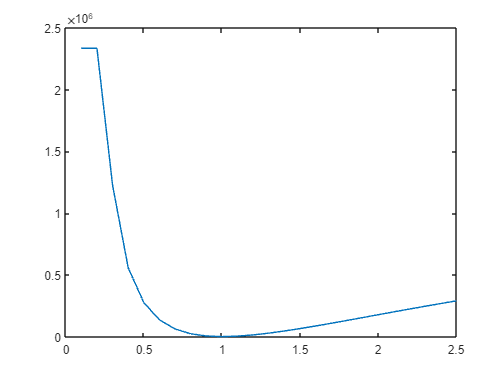

clear
alt =4300; %flight alt-- m
eta_d = .92; %inlet eff.
eta_n = .94; %nozzle eff.
A_e = .015; %m^2
M1 = 2.4;
Tt3_max = 2400; %k
qf = 42.3*10^6; %j/kg

M2= .1:.1:2.5;

Overall_efficiency_array = [];
Thrust_array = [];
TSFC_array = [];

for i = 1:length(M2)
    [~, ~,~,~, ~, ~, ~, ~, ~, ~, Overall_efficiency_array(i), ~,Thrust_array(i), ~, TSFC_array(i), ~, ~, q23(i)] = RamjetCalculator(alt, eta_d, eta_n, A_e, M1, M2(i), Tt3_max, qf);
end

plot(M2, q23)

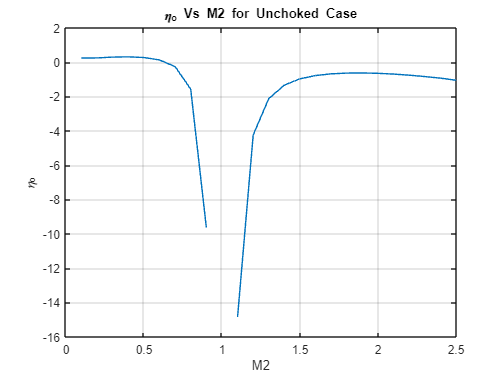


plot(M2,Overall_efficiency_array)
title('\eta_o Vs M2 for Unchoked Case')
xlabel('M2')
ylabel('\eta_o')
grid on

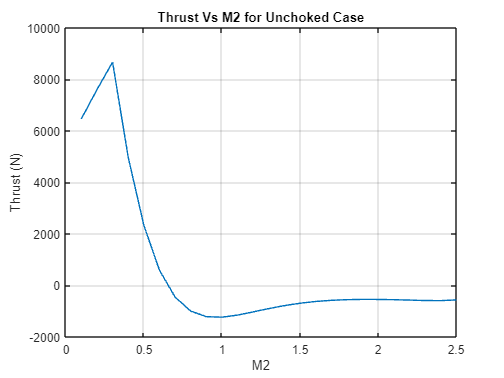


plot(M2,Thrust_array)
title('Thrust Vs M2 for Unchoked Case')
xlabel('M2')
ylabel('Thrust (N)')
grid on

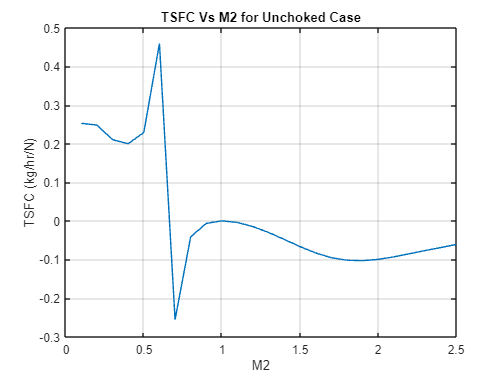


plot(M2,TSFC_array)
title('TSFC Vs M2 for Unchoked Case')
xlabel('M2')
ylabel('TSFC (kg/hr/N)')
grid on

## (i) Design Case

clear
M1 = 5;
alt = 27400;
qf = 42.3*10^6; %j/kg
eta_d = .92; %inlet eff.
eta_n = .94; %nozzle eff.
A_e = .015;

InputsTable = table(alt, eta_d, eta_n, A_e,M1,qf, 'VariableNames',{'Flight Altitude','Diffuser Eff.', 'Nozzle Eff.', 'A_e','M1', 'q_f' }  )

InputsTable = 1×6 table
    Flight Altitude    Diffuser Eff.    Nozzle Eff.     A_e     M1      q_f   
    _______________    _____________    ___________    _____    __    ________

         27400             0.92            0.94        0.015    5     4.23e+07



M2 = .1:.01:2.4;
Tt3 = 1500:10:2400;

[X,Y] = meshgrid(M2,Tt3);

for i = 1:length(Tt3)
    for j = 1:length(M2)
        [Overall_efficiency(i,j), Thrust(i,j)] = RamjetTt3DesignCalculator(alt, eta_d, eta_n, A_e, M1, X(i,j), qf, Y(i,j));
        if(Overall_efficiency(i,j)<0)
        end
    end
end

[MaxEfficiency, tempIndx]= max(Overall_efficiency,[],'all');
OptimizedEffTable = table(MaxEfficiency,X(tempIndx), Y(tempIndx), 'VariableNames',{'Max Efficiency', 'Optimal M2', 'Optimal Tt3'} )

OptimizedEffTable = 1×3 table
    Max Efficiency    Optimal M2    Optimal Tt3
    ______________    __________    ___________

       0.13105           0.4           2400    


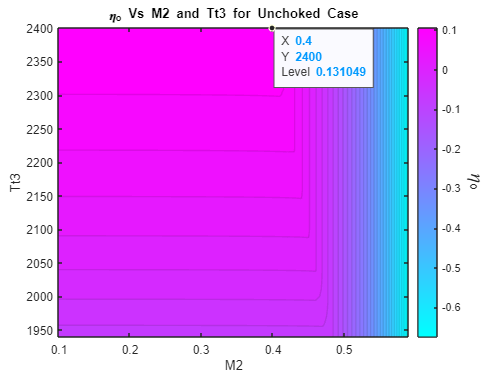

contourf(X(45:end, 1:50), Y(45:end, 1:50),Overall_efficiency(45:end, 1:50),30,'EdgeAlpha',0.1)
title('\eta_o Vs M2 and Tt3 for Unchoked Case')
h = colorbar;
xlabel('M2')
ylabel('Tt3')
h.Label.FontSize = 16;
h.Label.String = '\eta_o';
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";
ax = gca;
chart = ax.Children(1);
datatip(chart,X(tempIndx),Y(tempIndx));



[MaxThrust, tempIndx]= max(Thrust,[],'all');
OptimizedThrustTable = table(MaxThrust,X(tempIndx), Y(tempIndx), 'VariableNames',{'Max Thrust', 'Optimal M2', 'Optimal Tt3'} )

OptimizedThrustTable = 1×3 table
    Max Thrust    Optimal M2    Optimal Tt3
    __________    __________    ___________

      1983.9         0.41          2360    


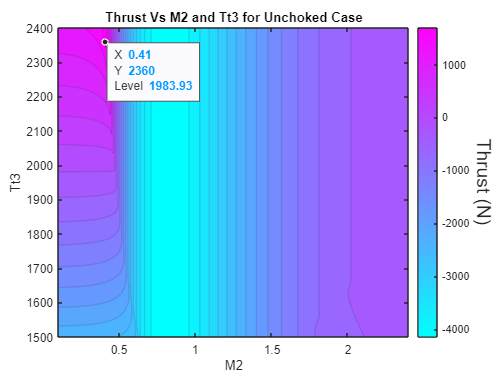


contourf(X, Y,Thrust,20, 'EdgeAlpha',0.1)
title('Thrust Vs M2 and Tt3 for Unchoked Case')
h = colorbar;
xlabel('M2')
ylabel('Tt3')
h.Label.FontSize = 16;
h.Label.String = 'Thrust (N)';
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";
ax = gca;
chart = ax.Children(1);
datatip(chart,X(tempIndx),Y(tempIndx));